Import the data

clear
A1 = readmatrix('data for k prediction.xlsx',Sheet='No adsorption type');
A2 = readtable('data for k prediction.xlsx','VariableNamingRule','preserve',Sheet='No adsorption type');
A2(:,1) = [];

alldatatrain = rmoutliers(A1(1:404,:),"mean","ThresholdFactor",2);
alldata = [alldatatrain; A1(405:407,:)];

%alldata = A1;

A3 = alldata;
A3(:,1) = [];


Normalize

alldatanorm(:,1) = alldata(:,1);
for  k = 2:7
    alldatanorm(:,k) = (alldata(:,k) - min(alldata(:,k)))/(max(alldata(:,k)) - min(alldata(:,k)));
end
alldatanorm(:,8) = alldata(:,8);
alldatanorm(:,9) = alldata(:,9);
alldatanorm(:,10) = alldata(:,10);
alldatanorm(:,11) = alldata(:,11);
alldatanorm(:,12) = alldata(:,12);


%alldatanor(:,1) = alldata(:,1);
%for  k = 2:7
%    mean1 = mean(alldata(:,k));
%    stdd = std((alldata(:,k)));
%    alldatanor(:,k) = (alldata(:,k) - mean1)/stdd;    
%end
%alldatanor(:,8) = alldata(:,8);

Adjust data

testdata = alldatanorm(261:263,:);
traindata1 = alldatanorm(1:260,:);

%x = [newtraindata.time newtraindata.temp newtraindata.surfaceArea];
%y = [newtraindata.adsorptionCapacity];

%xtest = [testdata_5.time testdata_5.temp testdata_5.surfaceArea];
%ytest = [testdata_5.adsorptionCapacity];

x = traindata1(:,2:7);
y = traindata1(:,8:9);

xtest1 = testdata(1,2:7);
ytest1 = testdata(1,8:9);

xtest2 = testdata(2,2:7);
ytest2 = testdata(2,8:9);

xtest3 = testdata(3,2:7);
ytest3 = testdata(3,8:9);

%xtest4 = testdata(4,2:7);
%ytest4 = testdata(4,8:9);

%xtest5 = testdata(5,2:7);
%ytest5 = testdata(5,8:9);

xtraininput = x';
ytrainoutput = y';
xtestinput1 = xtest1';
ytestoutput1 = ytest1';
xtestinput2 = xtest2';
ytestoutput2 = ytest2';
xtestinput3 = xtest3';
ytestoutput3 = ytest3';
%xtestinput4 = xtest4';
%ytestoutput4 = ytest4';
%xtestinput5 = xtest5';
%ytestoutput5 = ytest5';

Train an ANN loop

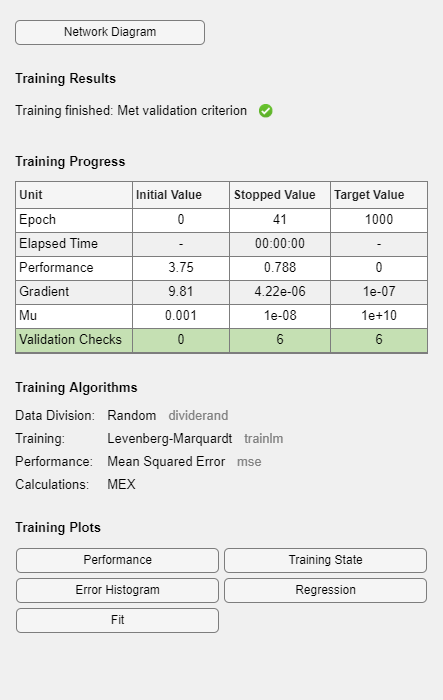

count = 1;
for i = 1:3
    for o = 1:100
        %defining the arch of the ANN
        
        trainFcn = 'trainlm';
        
        %hiddenlayersize = 3; 
        hiddenlayersize = [3 3 3 3 3 3];

        my_field2 = strcat('net',num2str(count));
        variable.(my_field2) = fitnet(hiddenlayersize,trainFcn);

        %hiddenLayerSize = o;
        %net = fitnet(hiddenlayersize,trainFcn);
        variable.(my_field2).layers{1}.transferFcn = 'logsig';
        %variable.(my_field2).layers{2}.transferFcn = 'tansig';
        %variable.(my_field2).layers{3}.transferFcn = 'tansig';
        %variable.(my_field2).layers{4}.transferFcn = 'logsig';
        %variable.(my_field2).layers{5}.transferFcn = 'logsig';
        %variable.(my_field2).layers{6}.transferFcn = 'logsig';
        variable.(my_field2).layers{2}.transferFcn = 'tansig';
        variable.(my_field2).divideParam.trainRatio = 70/100;
        variable.(my_field2).divideParam.valRatio = 15/100;
        variable.(my_field2).divideParam.testRatio = 15/100;
    
        [variable.(my_field2),tr] = train(variable.(my_field2),xtraininput,ytrainoutput);     

        %detemine the error of the ANN of training set
        yTrain = variable.(my_field2)(xtraininput(:,tr.trainInd)); 
        yTrainTrue_qe = ytrainoutput(1,tr.trainInd);
        yTrainTrue_k1st = ytrainoutput(2,tr.trainInd);
        RMSE_yTrain_qe(i,o) = sqrt(mean((yTrain(1,:) - yTrainTrue_qe).^2)); %RMSE of training set_qe
        RMSE_yTrain_k1st(i,o) = sqrt(mean((yTrain(2,:) - yTrainTrue_k1st).^2)); %RMSE of training set_k1st
        Rsq_yTrain_qe(i,o) = 1 - sum((yTrainTrue_qe - yTrain(1,:)).^2)/sum((yTrainTrue_qe - mean(yTrainTrue_qe)).^2);
        Rsq_yTrain_k1st(i,o) = 1 - sum((yTrainTrue_k1st - yTrain(2,:)).^2)/sum((yTrainTrue_k1st - mean(yTrainTrue_k1st)).^2);
    
        %detemine the error of the ANN of validate set
        yVal = variable.(my_field2)(xtraininput(:,tr.valInd)); 
        yValTrue_qe = ytrainoutput(1,tr.valInd);
        yValTrue_k1st = ytrainoutput(2,tr.valInd);
        RMSE_yVal_qe(i,o) = sqrt(mean((yVal(1,:) - yValTrue_qe).^2)); %RMSE of validate set_qe
        RMSE_yVal_k1st(i,o) = sqrt(mean((yVal(2,:) - yValTrue_k1st).^2)); %RMSE of validate set_k1st
        Rsq_yVal_qe(i,o) = 1 - sum((yValTrue_qe - yVal(1,:)).^2)/sum((yValTrue_qe - mean(yValTrue_qe)).^2);
        Rsq_yVal_k1st(i,o) = 1 - sum((yValTrue_k1st - yVal(2,:)).^2)/sum((yValTrue_k1st - mean(yValTrue_k1st)).^2);

        %detemine the error of the ANN of training set
        yTest = variable.(my_field2)(xtraininput(:,tr.testInd)); 
        yTestTrue_qe = ytrainoutput(1,tr.testInd);
        yTestTrue_k1st = ytrainoutput(2,tr.testInd);
        RMSE_yTest_qe(i,o) = sqrt(mean((yTest(1,:) - yTestTrue_qe).^2)); %RMSE of training set_qe
        RMSE_yTest_k1st(i,o) = sqrt(mean((yTest(2,:) - yTestTrue_k1st).^2)); %RMSE of training set_k1st
        Rsq_yTest_qe(i,o) = 1 - sum((yTestTrue_qe - yTest(1,:)).^2)/sum((yTestTrue_qe - mean(yTestTrue_qe)).^2);
        Rsq_yTest_k1st(i,o) = 1 - sum((yTestTrue_k1st - yTest(2,:)).^2)/sum((yTestTrue_k1st - mean(yTestTrue_k1st)).^2);

        %case test       
        ydatatest1 = variable.(my_field2)(xtestinput1); 
        ydatatest2 = variable.(my_field2)(xtestinput2);
        ydatatest3 = variable.(my_field2)(xtestinput3); 
        %ydatatest4 = variable.(my_field2)(xtestinput4); 
        %ydatatest5 = variable.(my_field2)(xtestinput5); 

        qe1(i,o) = ydatatest1(1,:);
        k1st1(i,o) = ydatatest1(2,:);

        qe2(i,o) = ydatatest2(1,:);
        k1st2(i,o) = ydatatest2(2,:);

        qe3(i,o) = ydatatest3(1,:);
        k1st3(i,o) = ydatatest3(2,:);

        %qe4(i,o) = ydatatest4(1,:);
        %k1st4(i,o) = ydatatest4(2,:);

        %qe5(i,o) = ydatatest5(1,:);
        %k1st5(i,o) = ydatatest5(2,:);
        o;
        count = count+1;
    end
    i;
end    

beep

Remove negative prediction values

all_q_and_k = [qe1;k1st1;qe2;k1st2;qe3;k1st3];
all_rmse_rsq = [RMSE_yTrain_qe;RMSE_yTrain_k1st;Rsq_yTrain_qe;Rsq_yTrain_k1st;
    RMSE_yVal_qe;RMSE_yVal_k1st;Rsq_yVal_qe;Rsq_yVal_k1st;
    RMSE_yTest_qe;RMSE_yTest_k1st;Rsq_yTest_qe;Rsq_yTest_k1st];

allforremoveneg = [all_q_and_k; all_rmse_rsq];
% Find columns with negative values
neg_cols = any(allforremoveneg(1:18,:) < 0, 1);

% Remove negative columns
allforremoveneg(:, neg_cols) = [];

%adjust qe and k to new matrix
qe1_rmv_neg = allforremoveneg(1:3,:);
k1_rmv_neg = allforremoveneg(4:6,:);
qe2_rmv_neg = allforremoveneg(7:9,:);
k2_rmv_neg = allforremoveneg(10:12,:);
qe3_rmv_neg = allforremoveneg(13:15,:);
k3_rmv_neg = allforremoveneg(16:18,:);
RMSEn_yTrain_qe = allforremoveneg(19:21,:);
RMSEn_yTrain_k1st = allforremoveneg(22:24,:);
Rsqn_yTrain_qe = allforremoveneg(25:27,:);
Rsqn_yTrain_k1st = allforremoveneg(28:30,:);
RMSEn_yVal_qe = allforremoveneg(31:33,:);
RMSEn_yVal_k1st = allforremoveneg(34:36,:);
Rsqn_yVal_qe = allforremoveneg(37:39,:);
Rsqn_yVal_k1st = allforremoveneg(40:42,:);
RMSEn_yTest_qe = allforremoveneg(43:45,:);
RMSEn_yTest_k1st = allforremoveneg(46:48,:);
Rsqn_yTest_qe = allforremoveneg(49:51,:);
Rsqn_yTest_k1st = allforremoveneg(52:54,:);

Error of case set

%error of qe of 5 case
[rownum,colnum]=size(allforremoveneg)

rownum = 54

colnum = 97

for num = 1:3
    err_qe1 = sqrt(((ytest1(:,1)) - qe1_rmv_neg(num,:)).^2);
    err_qe2 = sqrt(((ytest2(:,1)) - qe2_rmv_neg(num,:)).^2);
    err_qe3 = sqrt(((ytest3(:,1)) - qe3_rmv_neg(num,:)).^2);
    %err_qe4 = sqrt(((ytest4(:,1)) - qe4(num,:)).^2);
    %err_qe5 = sqrt(((ytest5(:,1)) - qe5(num,:)).^2);

    [min_qe1,ind_qe1] = min(err_qe1);
    [min_qe2,ind_qe2] = min(err_qe2);
    [min_qe3,ind_qe3] = min(err_qe3);
    %[min_qe4,ind_qe4] = min(err_qe4);
    %[min_qe5,ind_qe5] = min(err_qe5);

%sum of error
    err_q_all = [err_qe1;err_qe2;err_qe3]; %;err_qe4;err_qe5];
    for xb = 1:colnum
        sum_err_q_all(:,xb) = sum(err_q_all(:,xb));
    end

    [min_error,idx_min_error] = min(sum_err_q_all)

%index of qe1
    k1_rmv_neg(idx_min_error)
    qe1_rmv_neg(idx_min_error)
    k2_rmv_neg(idx_min_error)
    qe2_rmv_neg(idx_min_error)
    k3_rmv_neg(idx_min_error)
    qe3_rmv_neg(idx_min_error)
    %k1st4(idx_min_error)
    %qe4(idx_min_error)
    %k1st5(idx_min_error)
    %qe5(idx_min_error)
    
    minid(num,:) = idx_min_error;
    xb = [];
end

min_error = 0.4373

idx_min_error = 34

ans = 0.4592

ans = 0.8809

ans = 0.4545

ans = 0.8831

ans = 0.4493

ans = 0.8856

min_error = 0.7165

idx_min_error = 54

ans = 0.3352

ans = 1.6595

ans = 0.3347

ans = 1.6607

ans = 0.3343

ans = 1.6614

min_error = 0.9296

idx_min_error = 36

ans = 0.4539

ans = 0.8324

ans = 0.4361

ans = 0.8959

ans = 0.4071

ans = 1.0122


table_of_r_rmse = [Rsqn_yTrain_qe(1,minid(1,:)) RMSEn_yTrain_qe(1,minid(1,:)) Rsqn_yVal_qe(1,minid(1,:)) RMSEn_yVal_qe(1,minid(1,:)) Rsqn_yTest_qe(1,minid(1,:)) RMSEn_yTest_qe(1,minid(1,:)) Rsqn_yTrain_k1st(1,minid(1,:)) RMSEn_yTrain_k1st(1,minid(1,:)) Rsqn_yVal_k1st(1,minid(1,:)) RMSEn_yVal_k1st(1,minid(1,:)) Rsqn_yTest_qe(1,minid(1,:)) RMSEn_yTest_k1st(1,minid(1,:));
    Rsqn_yTrain_qe(2,minid(2,:)) RMSEn_yTrain_qe(2,minid(2,:)) Rsqn_yVal_qe(2,minid(1,:)) RMSEn_yVal_qe(2,minid(2,:)) Rsqn_yTest_qe(2,minid(2,:)) RMSEn_yTest_qe(2,minid(2,:)) Rsqn_yTrain_k1st(2,minid(2,:)) RMSEn_yTrain_k1st(2,minid(2,:)) Rsqn_yVal_k1st(2,minid(2,:)) RMSEn_yVal_k1st(2,minid(2,:)) Rsqn_yTest_qe(2,minid(2,:)) RMSEn_yTest_k1st(2,minid(2,:));
    Rsqn_yTrain_qe(3,minid(3,:)) RMSEn_yTrain_qe(3,minid(3,:)) Rsqn_yVal_qe(3,minid(1,:)) RMSEn_yVal_qe(3,minid(3,:)) Rsqn_yTest_qe(3,minid(3,:)) RMSEn_yTest_qe(3,minid(3,:)) Rsqn_yTrain_k1st(3,minid(3,:)) RMSEn_yTrain_k1st(3,minid(3,:)) Rsqn_yVal_k1st(3,minid(3,:)) RMSEn_yVal_k1st(3,minid(3,:)) Rsqn_yTest_qe(3,minid(3,:)) RMSEn_yTest_k1st(3,minid(3,:))];

table_of_k_q = [k1_rmv_neg(1,minid(1,:)) qe1_rmv_neg(1,minid(1,:));
    k1_rmv_neg(2,minid(2,:)) qe1_rmv_neg(2,minid(2,:));
    k1_rmv_neg(3,minid(3,:)) qe1_rmv_neg(3,minid(3,:));
    k2_rmv_neg(1,minid(1,:)) qe2_rmv_neg(1,minid(1,:));
    k2_rmv_neg(2,minid(2,:)) qe2_rmv_neg(2,minid(2,:));
    k2_rmv_neg(3,minid(3,:)) qe2_rmv_neg(3,minid(3,:));
    k3_rmv_neg(1,minid(1,:)) qe3_rmv_neg(1,minid(1,:));
    k3_rmv_neg(2,minid(2,:)) qe3_rmv_neg(2,minid(2,:));
    k3_rmv_neg(3,minid(3,:)) qe3_rmv_neg(3,minid(3,:))];
    %k1st4(1,minid(1,:)) qe4(1,minid(1,:));
    %k1st4(2,minid(2,:)) qe4(2,minid(2,:));
    %k1st4(3,minid(3,:)) qe4(3,minid(3,:));
    %k1st5(1,minid(1,:)) qe5(1,minid(1,:));
    %k1st5(2,minid(2,:)) qe5(2,minid(2,:));
    %k1st5(3,minid(3,:)) qe5(3,minid(3,:));];

genFunction & codegen

genFunction(variable.net68,'ANN_k','MatrixOnly','yes');

 
MATLAB function generated: ANN_k.m
To view generated function code: edit ANN_k
For examples of using function: help ANN_k
 


genFunction(variable.net68,'ANN_qe','MatrixOnly','yes');

 
MATLAB function generated: ANN_qe.m
To view generated function code: edit ANN_qe
For examples of using function: help ANN_qe
 


x1Type = coder.typeof(double(0),[7 Inf]); % Coder type of input 1
%codegen ANNfunction4.m -config:mex -o ANNCodeGen -args {x1Type}
codegen -d ANNfunctionlib -config:lib  ANNfunction5 -args {x1Type}

??? Not enough input arguments. Input 'w_c' is not supplied to this function or method.

Error in ==> ANNfunction5 Line: 38 Column: 11
Code generation failed: View Error Report



Error using codegen

for i = 1:30
    for o = 1:20
        %defining the arch of the ANN
        
        %hiddenLayerSize = o;
        net = fitnet(i);
        net.layers{1}.transferFcn = 'tansig';
        net.layers{2}.transferFcn = 'purelin';
        net.divideParam.trainRatio = 70/100;
        net.divideParam.valRatio = 15/100;
        net.divideParam.testRatio = 15/100;
        
        net.trainFcn ='trainscg';
        %training the Ann
        [net,tr] = train(net,xtraininput,ytrainoutput);
    
        %detemine the error of the ANN of training set
        yTrain = net(xtraininput(:,tr.trainInd)); 
        yTrainTrue_qe = ytrainoutput(1,tr.trainInd);
        yTrainTrue_k1st = ytrainoutput(2,tr.trainInd);
        RMSE_yTrain_qe(o) = sqrt(mean((yTrain(1,:) - yTrainTrue_qe).^2)); %RMSE of training set_qe
        RMSE_yTrain_k1st(o) = sqrt(mean((yTrain(2,:) - yTrainTrue_k1st).^2)); %RMSE of training set_k1st
        Rsq_yTrain_qe(o) = 1 - (sum((yTrainTrue_qe - yTrain(1,:)).^2)/sum((yTrainTrue_qe - mean(yTrainTrue_qe)).^2));
        Rsq_yTrain_k1st(o) = 1 - (sum((yTrainTrue_k1st - yTrain(2,:)).^2)/sum((yTrainTrue_k1st - mean(yTrainTrue_k1st)).^2));
    
        %detemine the error of the ANN of validate set
        yVal = net(xtraininput(:,tr.valInd)); 
        yValTrue_qe = ytrainoutput(1,tr.valInd);
        yValTrue_k1st = ytrainoutput(2,tr.valInd);
        RMSE_yVal_qe(o) = sqrt(mean((yVal(1,:) - yValTrue_qe).^2)); %RMSE of validate set_qe
        RMSE_yVal_k1st(o) = sqrt(mean((yVal(2,:) - yValTrue_k1st).^2)); %RMSE of validate set_k1st
        Rsq_yVal_qe(o) = 1 - (sum((yValTrue_qe - yVal(1,:)).^2)/sum((yValTrue_qe - mean(yValTrue_qe)).^2));
        Rsq_yVal_k1st(o) = 1 - (sum((yValTrue_k1st - yVal(2,:)).^2)/sum((yValTrue_k1st - mean(yValTrue_k1st)).^2));

        %detemine the error of the ANN of test set
        yTest = net(xtraininput(:,tr.testInd)); 
        yTestTrue_qe = ytrainoutput(1,tr.testInd);
        yTestTrue_k1st = ytrainoutput(2,tr.testInd);
        RMSE_yTest_qe(o) = sqrt(mean((yTest(1,:) - yTestTrue_qe).^2)); %RMSE of test_qe
        RMSE_yTest_k1st(o) = sqrt(mean((yTest(2,:) - yTestTrue_k1st).^2)); %RMSE of test_k1st
        Rsq_yTest_qe(o) = 1 - (sum((yTestTrue_qe - yTest(1,:)).^2)/sum((yTestTrue_qe - mean(yTestTrue_qe)).^2));
        Rsq_yTest_k1st(o) = 1 - (sum((yTestTrue_k1st - yTest(2,:)).^2)/sum((yTestTrue_k1st - mean(yTestTrue_k1st)).^2));
        o
    end
    av_rmse_train_qe(i) = mean(RMSE_yTrain_qe);
    av_rmse_val_qe(i) = mean(RMSE_yVal_qe);
    av_rmse_test_qe(i) = mean(RMSE_yTest_qe);
    av_rmse_train_k1st(i) = mean(RMSE_yTrain_k1st);
    av_rmse_val_k1st(i) = mean(RMSE_yVal_k1st);
    av_rmse_test_k1st(i) = mean(RMSE_yTest_k1st);
    av_rsq_train_qe(i) = mean(Rsq_yTrain_qe);
    av_rsq_val_qe(i) = mean(Rsq_yVal_qe);
    av_rsq_test_qe(i) = mean(Rsq_yTest_qe);
    av_rsq_train_k1st(i) = mean(Rsq_yTrain_k1st);
    av_rsq_val_k1st(i) = mean(Rsq_yVal_k1st);
    av_rsq_test_k1st(i) = mean(Rsq_yTest_k1st);
    i
end

plot(1:i,av_rmse_train_qe,'o-'); hold on
plot(1:i,av_rmse_val_qe,'x-');
plot(1:i,av_rmse_test_qe,'*-'); hold off
[mintq,itq] = min(av_rmse_train_qe)
[minvq,ivq] = min(av_rmse_val_qe)

plot(1:i,av_rmse_train_k1st,'o-'); hold on
plot(1:i,av_rmse_val_k1st,'x-'); 
plot(1:i,av_rmse_test_k1st,'*-'); hold off
[mintk,itk] = min(av_rmse_train_k1st)
[minvk,ivk] = min(av_rmse_val_k1st)

plot(1:i,av_rsq_train_qe,'o-'); hold on
plot(1:i,av_rsq_val_qe,'x-'); 
plot(1:i,av_rsq_test_qe,'*-'); hold off
[maxtq,irtq] = max(av_rsq_train_qe)
[maxvq,irvq] = max(av_rsq_val_qe)

plot(1:i,av_rsq_train_k1st,'o-'); hold on
plot(1:i,av_rsq_val_k1st,'x-'); 
plot(1:i,av_rsq_test_k1st,'*-'); hold off
[maxtk,irtk] = max(av_rsq_train_k1st)
[maxvk,irvk] = max(av_rsq_val_k1st)

rmse_all = [av_rmse_train_qe; av_rmse_val_qe; av_rmse_test_qe; av_rmse_train_k1st; av_rmse_val_k1st; av_rmse_test_k1st];
rsq_all = [av_rsq_train_qe; av_rsq_val_qe; av_rsq_test_qe; av_rsq_train_k1st; av_rsq_val_k1st; av_rsq_test_k1st];
Rmse_rsq = [rmse_all; rsq_all];